Esercizio 4

Confrontiamo i tempi di esecuzione della FFT con quella della FT calcolata come prodotto matriciale. Il test sarà fatto su istanze di dimensione variabile, di seguito il codice.

Calcolo del vettore delle dimensioni, ogni elemento è una potenza di due.

format long
N=zeros(1,11);
for i=1:11
    N(i) = 2^(i+2); 
end    

Inizializzazione dei vettori dei tempi t1 misura i tempi della FFT, t2 misura i tempi della FT.

trasf_prod=@(x,W) W*x;
t1=zeros(1,length(N));
t2=zeros(1,length(N));

Di seguito il ciclo for usato per il calcolo degli N tempi di esecuzione, nel ciclo for ci serviamo di un segnale x pari ad una finestra rettangolare di N/4 campioni, dunque di dimensione variabile ad ogni ciclo.

for i=1:length(N)
    n=[0:N(i)-1];
    k=[0:N(i)-1];
    x=zeros(N(i));
    L=N(i)/4;  %  25% di N(i)
    x(1:L)=1;                                                                 
    W=zeros(N(i),N(i));
    W=exp(-1i*2*pi*k'*n/N(i));                                                  
    X=W*x;                                              
    X1=fft(x);                                                                                                                                % Impulso rettangolare di durata L
    t1(i)=timeit(@() fft(x));
    t2(i)=timeit(@() trasf_prod(x,W));
end

Infine i grafici a confronto.

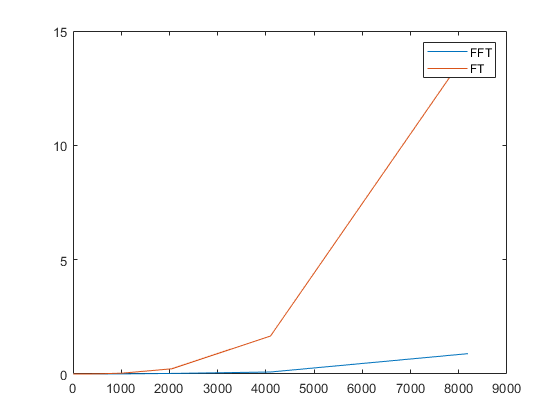

figure;plot(N,t1);
hold on;
plot(N,t2);legend('FFT','DFT');